# 画像生成のためのVariational Autoencoder (VAE) の学習と異常検知への適用

## データの読み込み

clear;clc;close all;rng(0);
training = true; % 学習をする場合true; 学習済みネットワークを使う場合はfalse。
% データの定義
imds = imageDatastore('trainingimage','IncludeSubfolders',true);
imdsTrain = subset(imds,1:38); % 38枚を学習に
imdsTest = subset(imds,39:40); % 2枚を評価に

Imgsize = [720 1280]; % 画像サイズ
BlockSize = [144  256]; % ネットワークの入力サイズ
numPatch =64;
% 学習時にランダムに画像を切り出して利用
dsTrain = randomPatchExtractionDatastore(imdsTrain,imdsTrain,BlockSize,'PatchesPerImage',numPatch); % ,'DataAugmentation',augmenter);
dsTest = randomPatchExtractionDatastore(imdsTest,imdsTest,BlockSize,'PatchesPerImage',4); % ,'DataAugmentation',augmenter);

numTrainImages = numel(imdsTrain.Files);

## ネットワークの構築

latentDim = 20; % 潜在空間の次元
imageSize = [BlockSize 3]; % ネットワークの入力サイズの指定
% Encoderのネットワーク定義
encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')    
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);
% Decoderのネットワーク定義
decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', [3 4], 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', [3 4], 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose4')
    reluLayer('Name','relu4')
    transposedConv2dLayer(3, 16, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose5')
    reluLayer('Name','relu5')
     transposedConv2dLayer(3, 16, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose6')
     reluLayer('Name','relu6')    
    transposedConv2dLayer(3, 3, 'Cropping', 'same', 'Name', 'transpose7')
    ]);

## dlnetworkに変換

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

## 学習オプションの設定

実行環境の設定

executionEnvironment = "auto";

numEpochs = 400; % Epoch数
miniBatchSize = numPatch; % ミニバッチサイズ
lr = 1e-4; % 学習率
numIterations = floor(numTrainImages/miniBatchSize); % Iteretion数
iteration = 0;
dsTrain.MiniBatchSize = miniBatchSize;

% adam optimizerの平均勾配と後続の平均勾配二乗減衰率を初期化
avgGradientsEncoder = [];
avgGradientsSquaredEncoder = [];
avgGradientsDecoder = [];
avgGradientsSquaredDecoder = [];

## モデルの学習

if training
% mkdir result
for epoch = 1:numEpochs
    tic;
    for i = 1:numTrainImages
        iteration = iteration + 1;
        % 学習用のデータを取り出し、dlarrayに変換
        PatchTrain = read(dsTrain);
        XBatch = PatchTrain.InputImage;
        XBatch = cat(4,XBatch{:});
        XBatch = dlarray(single(XBatch)/255, 'SSCB');
        % 実行環境がGPUの場合はgpuArrayに変換
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            XBatch = gpuArray(XBatch);           
        end 
        % Gradientの計算
        [infGrad, genGrad] = dlfeval(...
            @modelGradients, encoderNet, decoderNet, XBatch);
        % Encoder/Decoderのパラメータを更新
        [decoderNet.Learnables, avgGradientsDecoder, avgGradientsSquaredDecoder] = ...
            adamupdate(decoderNet.Learnables, ...
                genGrad, avgGradientsDecoder, avgGradientsSquaredDecoder, iteration, lr);
        [encoderNet.Learnables, avgGradientsEncoder, avgGradientsSquaredEncoder] = ...
            adamupdate(encoderNet.Learnables, ...
                infGrad, avgGradientsEncoder, avgGradientsSquaredEncoder, iteration, lr);
    end
    elapsedTime = toc;
    % エポックごとに読み取りデータをリセット
    reset(dsTrain);reset(dsTest);
    % 未知の画像でテスト
    PatchTest = read(dsTest);
    XTest= PatchTest.InputImage;
    XTest = dlarray(single(cat(4,XTest{:}))/255,'SSCB');
    % 入力画像をEncoder/Decoderに通す。
    [z, zMean, zLogvar] = sampling(encoderNet, XTest);
    xPred = sigmoid(forward(decoderNet, z));
    % 損失の計算
    elbo = ELBOloss(XTest, xPred, zMean, zLogvar);
    % 結果の表示
    disp("Epoch : "+epoch+" Test ELBO loss = "+gather(extractdata(elbo))+...
        ". Time taken for epoch = "+ elapsedTime + "s")
    xPredout = uint8(gather(extractdata(xPred))*255);
    subplot(1,2,1);imshow(PatchTest.InputImage{1})
    subplot(1,2,2);imshow(xPredout(:,:,:,1));shg
end
    save(["net.mat"],'decoderNet','encoderNet'); % 保存する
else
    load net
end

## 異常画像による検証

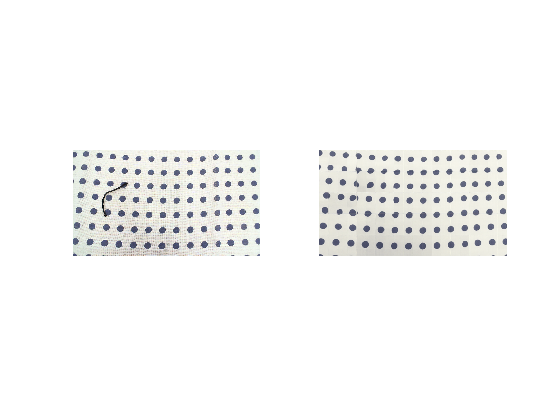

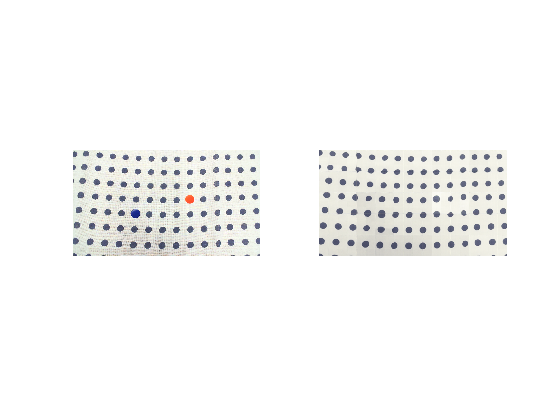

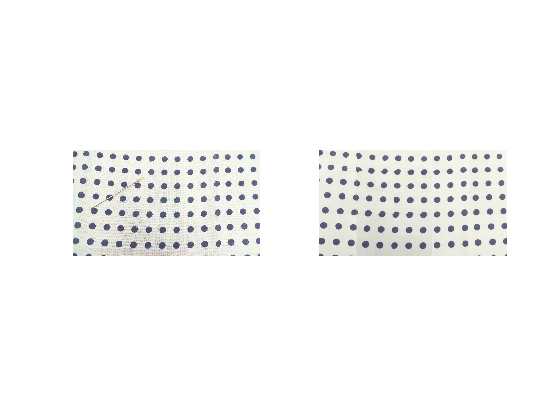

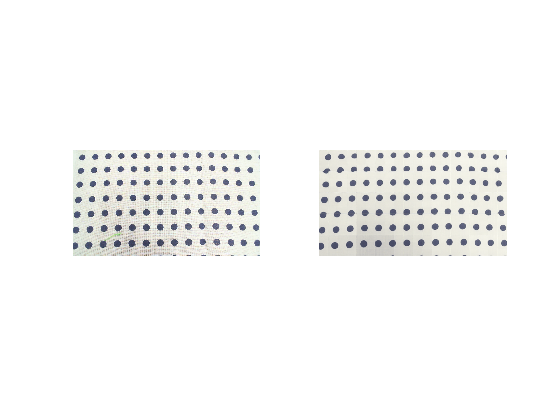

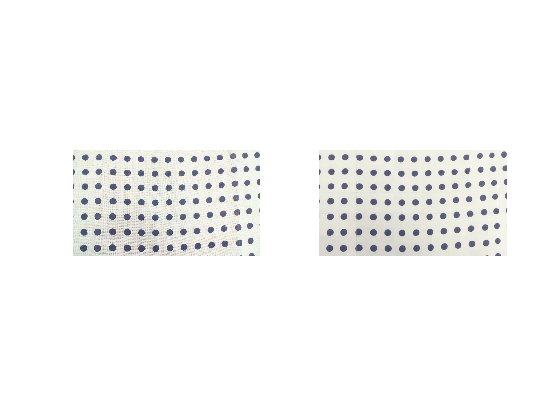

rng(0);
% 異物が混入した画像を評価用画像として定義
imdsval = imageDatastore('testimage','IncludeSubfolders',true,'LabelSource','foldernames');
% 変数の準備
I_All = uint8(zeros(Imgsize(1),Imgsize(2),3,numel(imdsTest.Files)));
BW = logical(zeros(Imgsize(1),Imgsize(2),1,numel(imdsTest.Files)));
Predicted_All = uint8(zeros(Imgsize(1),Imgsize(2),3,numel(imdsTest.Files)));
I_big =uint8(zeros(Imgsize(1),Imgsize(2),3));
Predicted_big =uint8(zeros(720,1280,3));

for nn=1:numel(imdsval.Files)
    I_big = read(imdsval); % 画像の読み出し
    % 大規模画像のためにブロック単位で処理していく
    fun = @(block_struct) mypredict(encoderNet, decoderNet,block_struct);
    Predicted_big = gather(blockproc(I_big,BlockSize,fun));
    Predicted_big = uint8(Predicted_big*255);
    % 推論結果と元画像の差分をla*b*空間でとる
    subt_temp = lab2rgb(imabsdiff( rgb2lab(I_big), rgb2lab(Predicted_big)));
    % 差分結果に対してしきい値を指定し異常個所を抽出する
    BW_mask = Maskedge(Predicted_big);
    BW_temp= createMask(subt_temp);
    BW_temp = BW_temp & BW_mask;
    BW_temp = imfill(BW_temp,'holes'); 
    BW_temp = bwareaopen(BW_temp,400,4);

    % 画像を統合していく
    I_All(:,:,:,nn) = I_big;
    Predicted_All(:,:,:,nn) = Predicted_big;
    BW(:,:,:,nn) = BW_temp;
    % 各入力画像と出力画像、差分結果、セグメンテーション結果を並べて表示する
    figure,
    subplot(1,2,1);imshow(I_big)
    subplot(1,2,2);imshow(Predicted_big);
%     subplot(2,2,3);imshow(subt_temp);    
%     subplot(2,2,4);imshow(BW_temp);
    shg
end

## 結果を重ねて表示する

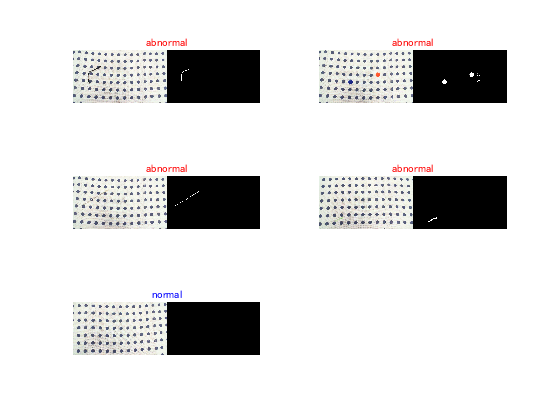

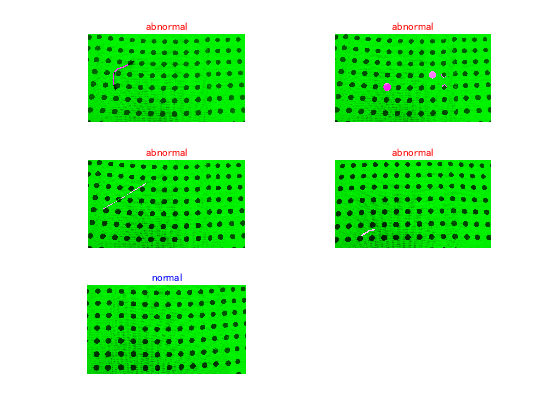

Color = {'r','r','r','r','b'};
f1 = figure;
f2 = figure;

for k = 1:numel(imdsval.Files)
    % 結果を並べて表示
    figure(f1), subplot(3,2,k), imshowpair(uint8(I_All(:,:,:,k)),BW(:,:,k),'montage');shg
    title(imdsval.Labels(k),'FontSize',20,'Color', Color{k});
    figure(f2),subplot(3,2,k), imshowpair(uint8(I_All(:,:,:,k)),BW(:,:,k));shg
    title(imdsval.Labels(k),'FontSize',20,'Color', Color{k});
end

## 補助関数

Model Gradients Function modelGradients関数は、エンコーダーとデコーダーのdlnetworkオブジェクトと入力データXのミニバッチを受け取り、ネットワーク内の学習可能なパラメーターに関する損失の勾配を返します。 この関数は3つの操作を実行します。

## 補助関数

損失勾配の計算をする関数 # エンコーダーネットワークを通過する画像のミニバッチでサンプリング関数を呼び出して、エンコードを取得します。 # デコーダーネットワークを介してエンコードを渡し、ELBOloss関数を呼び出して損失を取得します。 # dlgradient関数を呼び出して、両方のネットワークの学習可能なパラメーターに関する損失の勾配を計算します。

function [infGrad, genGrad] = modelGradients(encoderNet, decoderNet, x)
[z, zMean, zLogvar] = sampling(encoderNet, x);
xPred = sigmoid(forward(decoderNet, z));
loss = ELBOloss(x, xPred, zMean, zLogvar);
[genGrad, infGrad] = dlgradient(loss, decoderNet.Learnables, ...
    encoderNet.Learnables);
end

% サンプリング関数
% サンプリング関数は、入力画像からエンコーディングを取得します。 最初に、エンコーダネットワークを介して画像のミニバッチを渡し、サイズ（2 * latentDim）* 
% miniBatchSizeの出力を、平均の行列と分散の行列に分割します。各行列は、潜在的なサイズが* batchSizeです。 次に、これらの行列を使用して、再パラメーター化のトリックを実装し、エンコードを計算します。 
% 最後に、このエンコードをSSCB形式のdlarrayオブジェクトに変換します。
function [zSampled, zMean, zLogvar] = sampling(encoderNet, x)
compressed = forward(encoderNet, x);
d = size(compressed,1)/2;
zMean = compressed(1:d,:);
zLogvar = compressed(1+d:end,:);

sz = size(zMean);
epsilon = randn(sz);
sigma = exp(.5 * zLogvar);
z = epsilon .* sigma + zMean;
z = reshape(z, [1,1,sz]);
zSampled = dlarray(z, 'SSCB');
end
% 損失関数
% ELBOloss関数は、平均値のエンコーディングとサンプリング関数によって返された分散を取得し、それらを使用してELBO損失を計算します。
function elbo = ELBOloss(x, xPred, zMean, zLogvar)
squares = 0.5*(xPred-x).^2;
reconstructionLoss  = sum(squares, [1,2,3]);
KL = -.5 * sum(1 + zLogvar - zMean.^2 - exp(zLogvar), 1);
elbo = mean(reconstructionLoss + KL);
end
% 推論用関数
function xPred = mypredict(encoderNet, decoderNet, block_struct)
    XEval = dlarray(single(imresize(block_struct.data,[144 256]))/255,'SSC');
    [z, ~, ~] = sampling(encoderNet, XEval);
    xPred = sigmoid(forward(decoderNet, z));
    xPred = extractdata(xPred);
    % figure,imshow(xPred)
end
% 後処理用関数
% 模様の境界は誤差が起こるのでそこにマスク
function BW = Maskedge(RGB)
I = rgb2hsv(RGB);
% Hueに対して範囲を指定
channel1Min = 0.545;
channel1Max = 0.801;
% Saturationに対して範囲を指定
channel2Min = 0.138;
channel2Max = 1.000;
% Valueに対して範囲を指定
channel3Min = 0.000;
channel3Max = 1.000;

% 範囲に基づきマスクを作成
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW1 = sliderBW;
% できたマスクをモルフォロジー処理で整理
BW1 = imfill(BW1,'holes');
BW_L = imdilate(BW1,strel('disk',2,4));
BW_S = imerode(BW1,strel('disk',10,4));
BW = ~BW_L;
end
% 異常箇所のセグメンテーション
function BW = createMask(RGB)
RGB = mat2gray(RGB);
I = rgb2hsv(RGB);
% Hueの範囲を指定
channel1Min = 0.000;
channel1Max = 1.000;
% Saturationの範囲を指定
channel2Min = 0.000;
channel2Max = 1.000;
% Valueの範囲を指定
channel3Min = 0.315;
channel3Max = 1.000;
% 指定した範囲でマスクを作成
sliderBW = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;
end

*Copyright 2019 The MathWorks, Inc.*